# Render a Scene using a fisheye lens

We read in a PBRT file and render it through a pinhole. 

Then we render the same data through a fisheye lens.

Dependencies: ISET3d, **ISETLens, **ISETCam (or ISETBio), 

**See also**

    t_piIntro*, **isetlens** repository

## Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the PBRT input scene

thisR = piRecipeDefault('scene name','chessSet');

Read 9 materials.
Read 3 textures.
***Scene parsed.


This is a quick rendering of the PBRT scene through a pinhole optics

piWrite(thisR);
[scene, result] = piRender(thisR,'render type','radiance');

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.95
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   3.63
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   8.09
Complete render took: 1.38e+01 seconds.*** Rendering time for ChessSet:  13.8 sec ***

exr2bin done.

Have a look

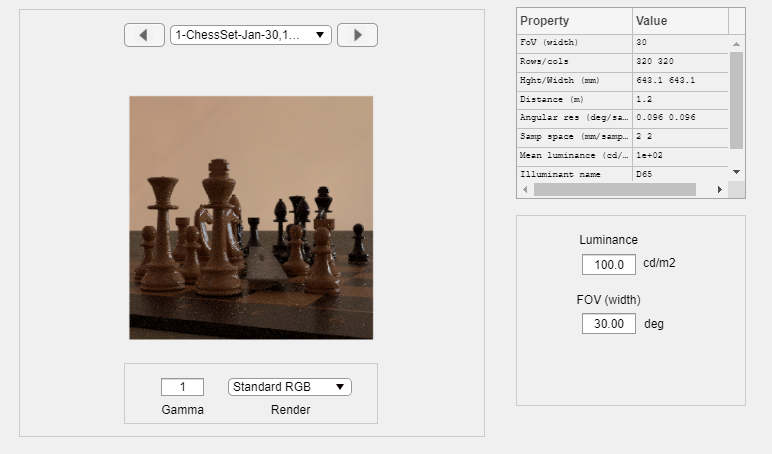

sceneWindow(scene);

## Set render quality

Set resolution for speed or quality.

thisR.set('film resolution',round([600 400]*0.5));
quality = 1;   % 1 is fast/low 20 is high/slow
thisR.set('pixel samples',64*quality);   % Number of rays set the quality.

## Add camera with a fisheye lens

You could also try these lens files. lensfile = 'dgauss.22deg.6.0mm.json'; lensfile = 'wide.40deg.6.0mm.json';

lensfile = 'fisheye.87deg.6.0mm.json';


If isetlens is on the path, we can look at the lens and some of its properties.  Check by whether folder 'lensC' exists.

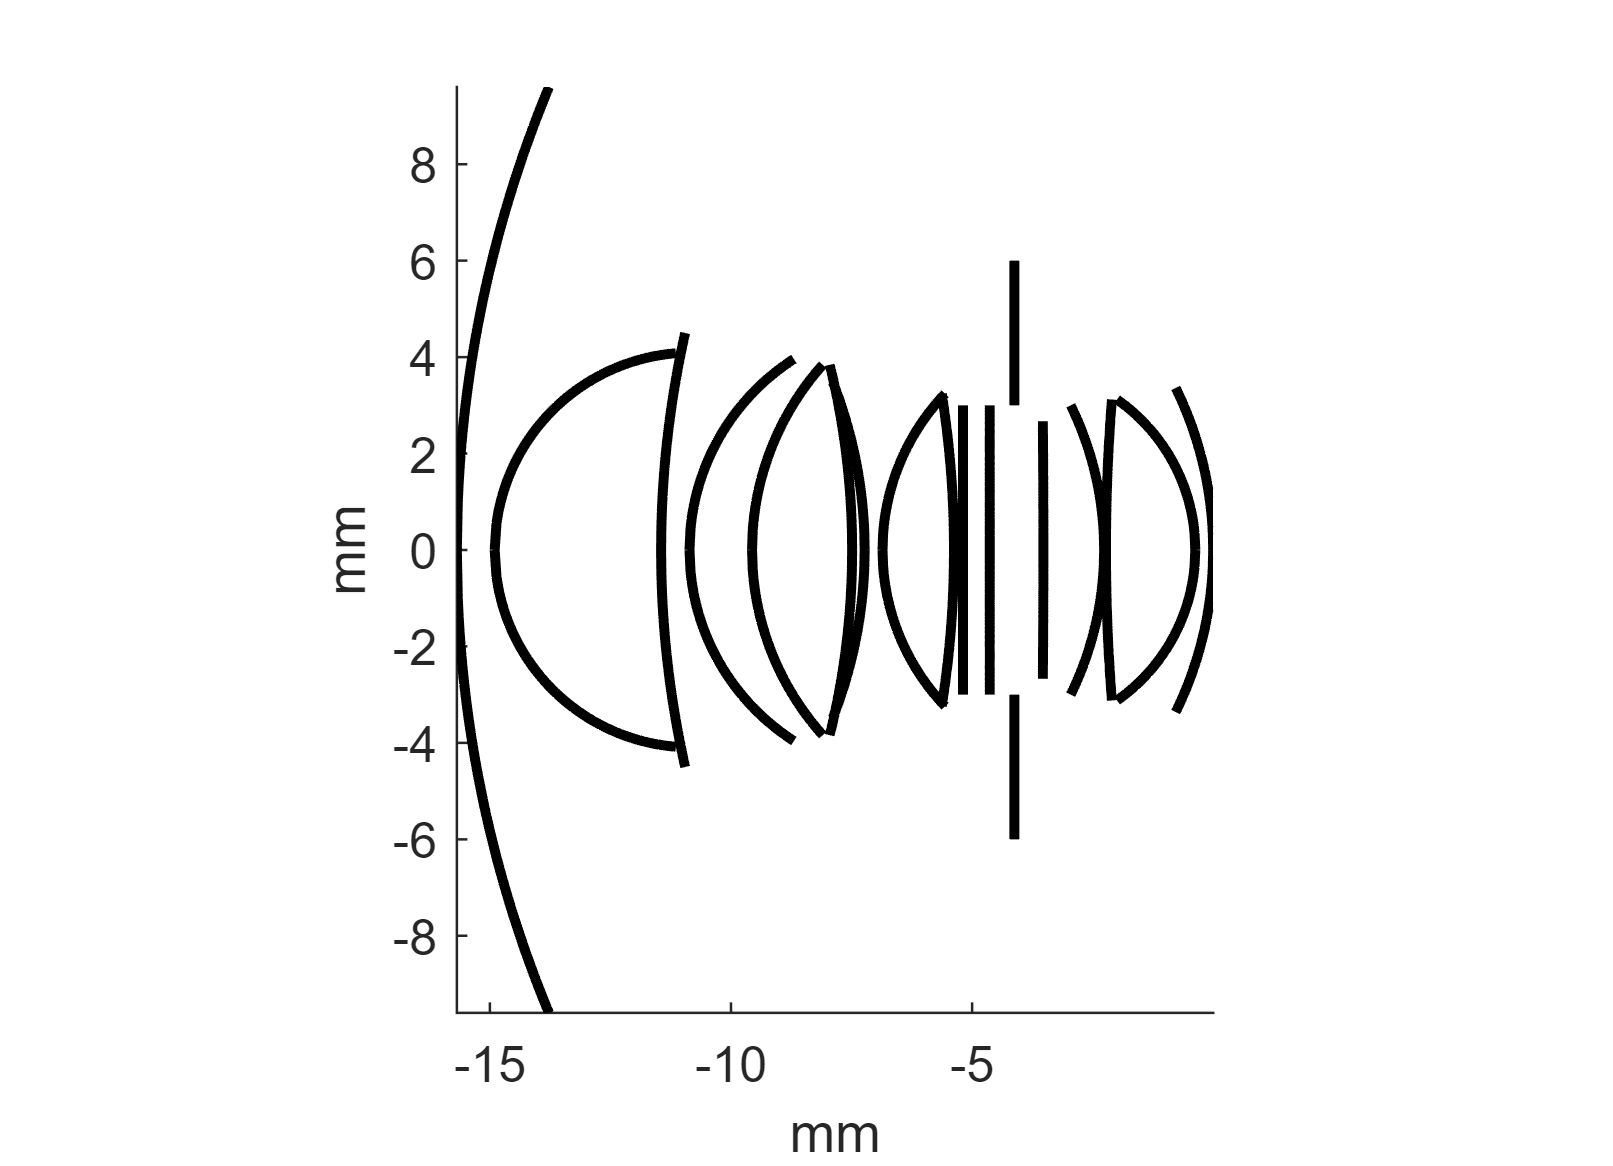

if exist('lensC','file')
    % If isetlens is on the path ....
    thislens = lensC('filename',lensfile);
    thislens.draw;
    % thislens.plot('focal distance');
end

Create a camera with the lens.

thisR.camera = piCameraCreate('omni','lensFile',lensfile);

PBRT estimates the distance.  It is not perfectly aligned to the depth map, but it is close.

thisR.set('focus distance',0.45);

This is the size of the film/sensor in millimeters

thisR.set('film diagonal',10);

Set rendering properties. We can use bdpt if you are using the docker with the "test" tag (see header). Otherwise you must use 'path'

thisR.integrator.subtype = 'path';  
thisR.sampler.subtype = 'sobol';

Lens aperture size

thisR.set('aperture diameter',3);

This value determines the number of ray bounces.  If the scene has glass or mirrors, we need to have at least 2 or more, but this increases rendering time.

thisR.set('nbounces',1);

## Write the recipe with the lens and render.

The output is an optical image.

oi = piWRS(thisR);

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.96
Render: docker --context render-vista exec -i  pbrt-gpu-Windows17758 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   5.79
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   8.27
Complete render took: 1.61e+01 seconds.*** Rendering time for ChessSet:  16.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


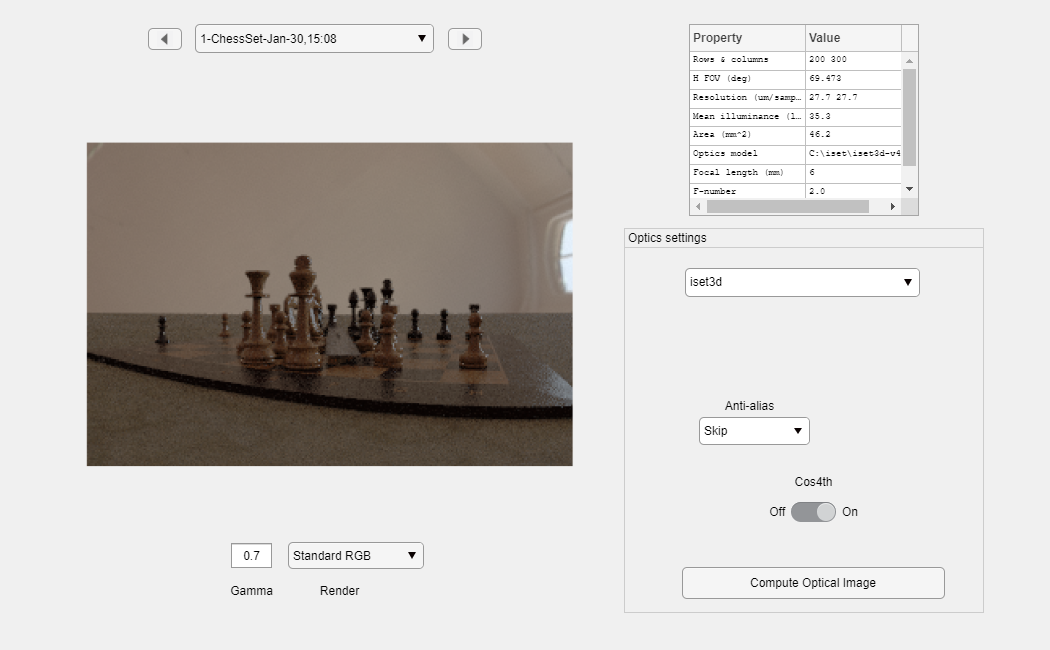

oiSet(oi,'gamma',0.7);